# 適応モデル予測制御を使用した車両のレーンチェンジ シミュレーション

本例題では、非線形な車両の並進モデルを元に走行時のレーンチェンジをモデル予測制御によって制御することを想定する。

プラントは、縦、横方向位置と進行方向に対する経路角度、自車速度の4状態量を有する非線形モデルである。

操作量は車両の加速度とステアリング舵角の2つである。

プラントモデルは非線形システムであるため、逐次線形近似を制御周期毎に行い、適応モデル予測制御によって車両制御を行う。

なお、本シミュレーションではVehicle Dynamics BlocksetのSimulation 3D Animation機能を利用しているため、Unreal Engineを用いた3Dアニメーションによる可視化を行うことが出来る。

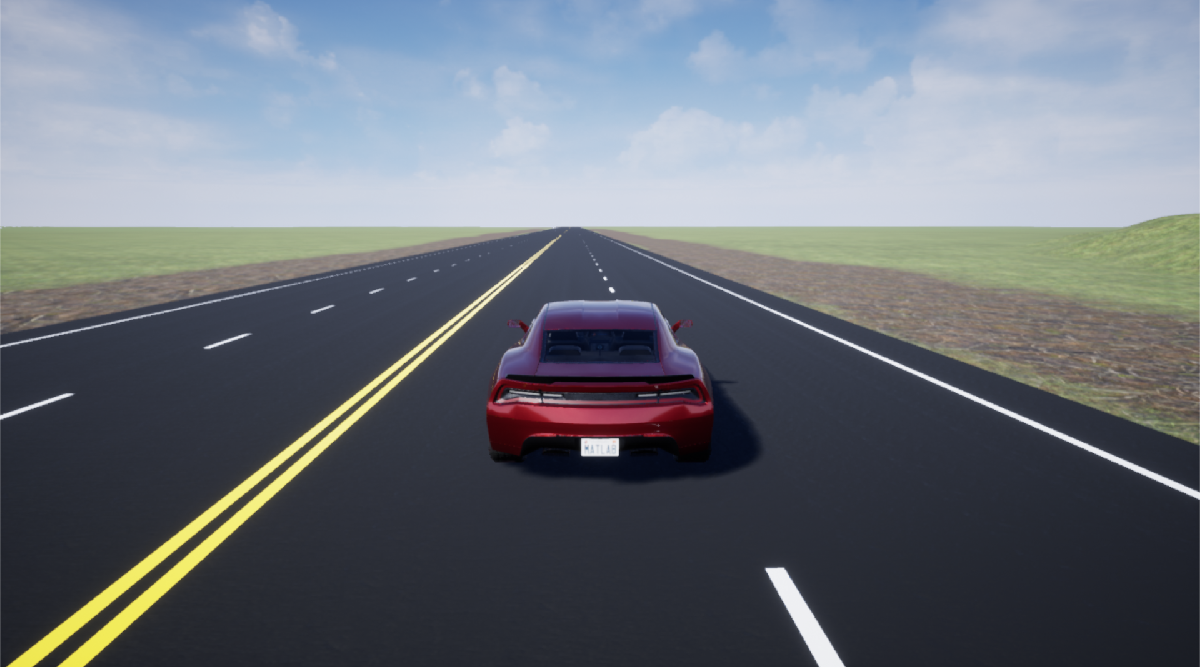

Vehicle Dynamics Blocksetを持っていない場合には、モデルのPlantサブシステム内、Simulation 3D Configurationブロック、Simulation 3D Vehicle with Ground Followingブロックをコメントアウトすれば、シミュレーションを行うことは可能である。

clc,clear

mdl = 'laneChangeNonLinCar';
open_system(mdl)

Ts = 0.02;              %サンプリング時間
V = 20;                 %縦方向速度の目標値（一定値）
Yref = -5;              %横方向位置の目標値（パルス信号の振幅）
x0 = [0; 0; 0; V];      %初期状態量ベクトル
u0 = [0; 0];            %初期入力ベクトル

MPC制御パラメ－ターを設定する。

% Control params
params.Q = diag([0,100,0,100]);         %出力の重み
params.R = diag([1,1]);                 %入力の重み
params.PredictiveHorizon = 60;          %予測ホライズン
params.ControlHorizon = 2;              %制御ホライズン
params.MV_max = [0.1;30*pi/180];        %入力制約
params.MV_min = -[0.1;30*pi/180];
params.dMV_max = [0.2*Ts;2*pi/30*Ts];   %入力変化率制約
params.dMV_min = [-0.2*Ts;-2*pi/30*Ts];
params.OV_max = [9999;100;pi/2;200];    %出力制約
params.OV_min = [0;-100;-pi/2;-10];
params.MV_scalefactor = [0.1;30*pi/180];%入力のスケールゲイン
params.OV_scalefactor = [1;10;1;V];     %出力のスケールゲイン
params.SolverType = 1;                  %ソルバータイプ：Active Set
params.IterationMax = 100;              %ソルバーによる最大イテレーション回数

AMPCにて必要となるバスオブジェクトは専用のAPIを使用してワークスペースに作成できる。

% Create sysBus object
n = 4;          %状態量の次数
m = 2;          %操作量の次数
l = 4;          %出力の次数
nd = 0;         %外乱の次数
sysBus = createSysBusObject(n,m,nd,l);

シミュレーションを実行する。

Tsim = 20;
tic
sim(mdl,Tsim)
toc

経過時間は 34.491251 秒です。
